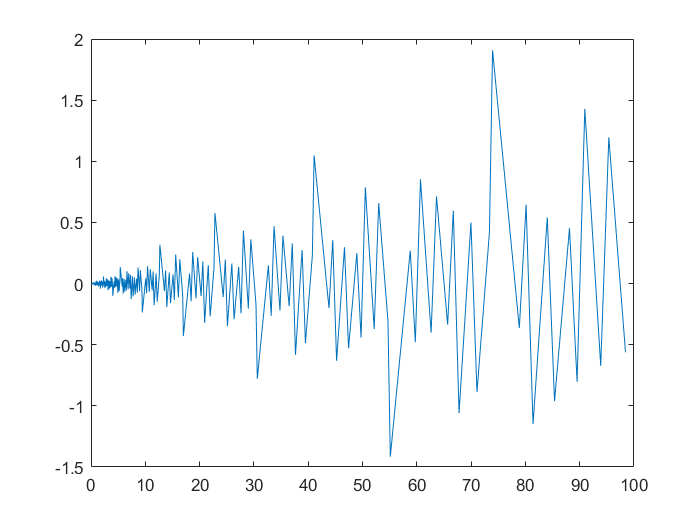

clc
clear all

syms x1 x2;
f = x1 ^ 2 / 2 + 50 * x2 ^ 2;
x = [100; 1];
epsilon = 1e-8;
a = 0.4;
b = 0.5;
x1_ax = [];
x2_ax = [];
f_ax = [];

d = -[diff(f,x1);diff(f,x2)];
flag = 1;
k = 0; 
while(flag)
    t = 1;
    d_temp = double(subs(subs(d,x1,x(1)),x2,x(2)));
    f_org = double(subs(subs(f,x1,x(1)),x2,x(2)));
    nor = double(norm(d_temp));
    if(nor >= epsilon)
        flag1 = 1;
        while(flag1)
           x_temp = x + t * d_temp;
           f_temp = double(subs(subs(f,x1,x_temp(1)),x2,x_temp(2)));
           if(f_temp > (f_org - a * t * nor ^ 2))
               t = b * t;
           else
               flag1 = 0;
           end
        end
        x = x + t * d_temp;
        x1_ax = [x1_ax, x(1)];
        x2_ax = [x2_ax, x(2)];
        f_ax = [f_ax, double(subs(subs(f,x1,x(1)),x2,x(2)))];
        k = k + 1;
    else
        flag=0;
    end
end
plot(x1_ax,x2_ax)

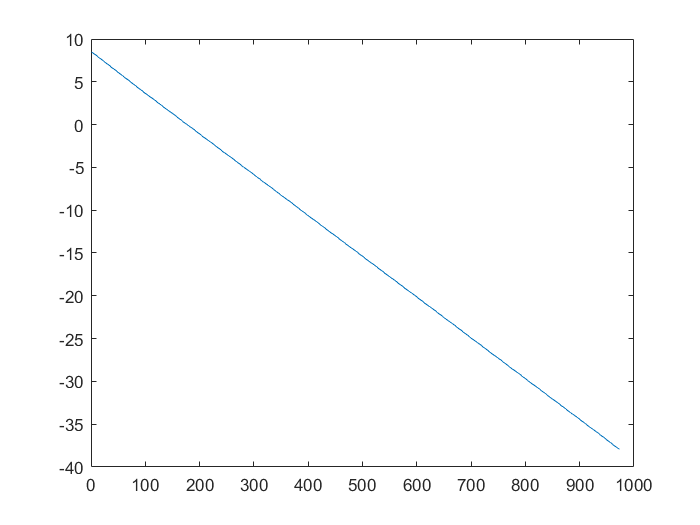

plot(log(f_ax))